% conjugate gradient
%n=input("Enter the roll number:");
beta = 8;

syms x1 x2 
fselect = 1;

switch fselect
    case 0
        % quadratic function 
        fobj = @(x) (x(1)).^2 + beta*x(2).^2; 
        %gradobj = @(x) 2*[x(1), (beta*x(2))];
        f = @(x1, x2) x1.^2 + beta*x2.^2;
        x0=[10, 1];
        xc1 = -5:0.1:12; xc2 = -7:0.1:7;
    case 1
        % The bean functon
        f = @(x1, x2) (1-x1).^2 + (1-x2).^2 + (0.5)*(2*x2 - x1.^2).^2
        fobj = @(x) (1-x(1)).^2 + (1-x(2)).^2 + (0.5)*(2*x(2) - x(1).^2).^2;
        x0 = [-1 , 2];
        xc1 = -3:0.1:3; xc2 = -1:0.1:3;
    case 2
        % ic5 2022
        f = @(x1,x2) x1.^2 .*exp(1-x1.^2 - 20.25*(x1 - x2).^2)
        fobj = @(x) x(1).^2 *exp(1 - x(1).^2 - 20.25*(x(1) - x(2)).^2)
        x0 = [0.1, 0.1];
        xc1 = -0.7:0.1:2.0; xc2 = -0.3:0.1:0.5;
    otherwise
end

f = function_handle with value:
    @(x1,x2)(1-x1).^2+(1-x2).^2+(0.5)*(2*x2-x1.^2).^2




gf = matlabFunction(gradient(f(x1,x2),[x1,x2]));

N = 500;
X = zeros(2,N); EG = 1e-6; EA = 1e-10; ER = 1e-10;
th0 = 1e-5;
X(:,1) = x0;
EG = 1e-10;

%============================================================
% Main loop
k = 2; 
x0 = [10; 1]

x0 =     10
     1


x = x0; Q = eye(2);
while (norm(gf(X(1,k-1), X(2,k-1))) >= EG) && k < N
    g = gf(X(1,k-1), X(2,k-1));
    
    linedir = -Q*g;
    % line search section
    fline = @(alpha) fobj(X(:,k-1) + alpha*linedir);
    [a,b] = bracket_minimumsp(fline);
    alpha = fminbnd(fline,a, b);

    % update all parameter
    xprime = X(:,k-1) - alpha*Q*g;
    gprime = gf(xprime(1), xprime(2));
    delta = xprime - X(:,k-1);
    gamma = gprime - g;

    Q = Q - (delta*gamma'*Q + Q*gamma*delta')/(delta'*gamma) + ...
            (1 + (gamma'*Q*gamma)/(delta'*gamma))*(delta*delta')/(delta'*gamma);

    X(:,k) = xprime;
    
    if k > 1
        nX = abs(fobj(X(:,k)) - fobj(X(:,k-1)));
        if  nX < EA + ER * abs(fobj(X(:,k-1)))
            break;
        end
    end
    k = k+1;
end


X = X(:,1:k);
fprintf("Using %d iteration", k-1);

Using 8 iteration

fprintf("Optimal solution x=%f,%f\n",X(:,end-1));

Optimal solution x=1.213412,0.824123


fprintf("Optimal value f(x)= %d \n",fobj(X(:,end-1)));

Optimal value f(x)= 9.194382e-02 


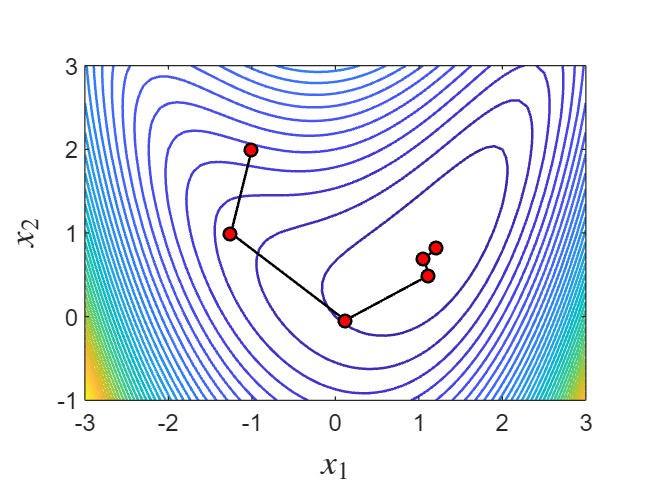


%========================================================

[Xc,Yc] = meshgrid(xc1,xc2);
Zc = f(Xc,Yc);

% Select contour plot for different funcition
switch fselect
    case 0
    % quadratic function
        contour(Xc,Yc,Zc, -100:40:800, 'LineWidth',1);
    case 1
    % bean function 
        contour(Xc,Yc,Zc, -500:2:100, 'LineWidth',1);
    case 2
        contourf(Xc,Yc,Zc, 'LineWidth',1);
    otherwise
end

xlabel("$x_1$",'Interpreter','latex',FontSize=14);
ylabel("$x_2$","FontSize",14,'Interpreter','latex')
hold on;
    plot(X(1,:), X(2,:), '-ok','linewidth', 1,...
        'MarkerFaceColor','red', 'MarkerEdgeColor','black',...
        'markersize', 5)
    axis equal
hold off;